# District Heating Pipe - Object based implementation

In a district heating network, where a high number of pipes (and other component) exist, generating equations for each pipe individually is not efficient. For this purpose, object oriented approach based on classes are generated

(For the basic implementation of a district heating pipe in the MTI-framework, please refer to [Basic Implementation](matlab:open('DistrictHeatingPipeDemo.mlx')) )

### Examplary Problem Formulation

Let us take a look at the following example. 

In this simple case, 3 nodes exists with with 4 objects (2 pipes and 2 sinks).

clear all; clc;

The pipes can also be generated using a call to a DisaggregatedPipe class. 

pipe1 = DisaggregatedPipe(di=263*1e-3, l=100, delta_x=50, initiateModel=true, pipeName='Pipe_1');

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Info: Multiple Inputs have the same name. They will be converted into one similar input!


Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


pipe2 = DisaggregatedPipe(di=234.5*1e-3, l=100, delta_x=50, initiateModel=true, pipeName='Pipe_2');

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 1 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Info: Multiple Inputs have the same name. They will be converted into one similar input!


Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.


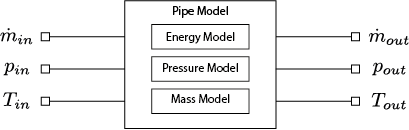

In the pipe model, the direction of $\dot{m}$ is defined as follow

- $\dot{m}_{in} \rightarrow +$ (going into the system)

- $\dot{m}_{out} \rightarrow -$ (leaving the system)

If for example Pipe 1 and Pipe 2 are connected to each other, $\dot{m}_{out, 1} $ has to be connected with $\dot{m}_{in, 2} $. 

Due to the definition implemented in this model, another equation is required to reverse the sign of $\dot{m}_{out,1}$ from negative to positive. 

Using objects called FluidConnector, the connection between inlet and outlet can be modelled.

As the direction for the temperature $T$ and pressure $p$ is not relevant, both of these variables can be set to be equal.


$$\dot{m}_{in} + \dot{m}_{out} = 0 \\
p_{in} - p_{out} = 0 \\
T_{in} - T_{out} = 0$$


connector1 = FluidConnector(from_object="Pipe_1", from_type ='outlet',  to_object="Pipe_2", to_type='inlet');
connector2 = FluidConnector(from_object="Pipe_2", from_type ='outlet',  to_object="Sink_3", to_type='inlet');
connector2.connectorModel.symbolicEquations

$$ans = \left(\begin{array}{c} y_{1}+y_{4}=0\\ y_{2}-y_{5}=0\\ y_{3}-y_{6}=0 \end{array}\right)$$

Within the context of this modelling framework, the direction of the mass flow $\dot{m}$ is represented using a boolean variable $z_{\dot{m}}$, which is later used to generate the absolute value of the mass flow $\dot{m}_{abs}$. 

If multiple "pipes", with its own boolean variable $z_{\dot{m}}$,  are connected to each other, the simulation breaks, when the direction of the mass flow changes. This occurs due to multiple switching events (inequalities) triggering at exactly the same time. This constillation may cause Zeno behavior (or also chattering) to occurs leading to no results being found for the discrete events. 

This can be avoided by applying a single boolean variable $z_{\dot{m}}$ for every pipe with identical mass flow. In other words for every pipe connected in a row.  

This is implemented using an object called FluidDirectionBool. 

This object makes use of the following equation


$$2 \cdot \dot{m}_{in} \cdot z_{\dot{m}} - \dot{m}_{in} \leq 0$$


Out of this equation, the following relation holds

- For $\dot{m}_{in} \le 0 \rightarrow z_{\dot{m}_{abs}} = 0$

- 
$$\dot{m}_{in} \gt 0 \rightarrow z_{\dot{m}_{abs}} = 1$$


fluiddirection = FluidDirectionBool(inletObject='Pipe_1', booleanName='mass_flow_bool');
fluiddirection.fluidDirectionModel.symbolicEquations;

Using two pipes as an example, the following schema can be made

The following constillation can now be connected together

mdl = connect(fluiddirection.fluidDirectionModel, ...
    pipe1.pipeModel, ...
    connector1.connectorModel, ...
    pipe2.pipeModel, ...
    connector2.connectorModel);

Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 11 column(s) and 0 equation(s) with trivial Reduction due to duplications.


% Get the index of the outputs generated from the simulation
output_strings = ["Sink_3_m_inlet", "Sink_3_t_inlet", "Sink_3_p_inlet"];
idx = find(ismember(mdl.algebraicName, output_strings));
disp(strcat('The index of "', output_strings, '" is:  ', string(idx))')

    "The index of "Sink_3_m_inlet" is:20"
    "The index of "Sink_3_t_inlet" is:21"
    "The index of "Sink_3_p_inlet" is:22"



Let us now simulate an example 

- Starting temperature of 30°C for the pipe

- 30°C constant inflow temperature

- 2 bar starting pressure

- linearly increasing mass flow from -2.5 $\frac{m}{s}$  to 2.5 $\frac{m}{s}$  

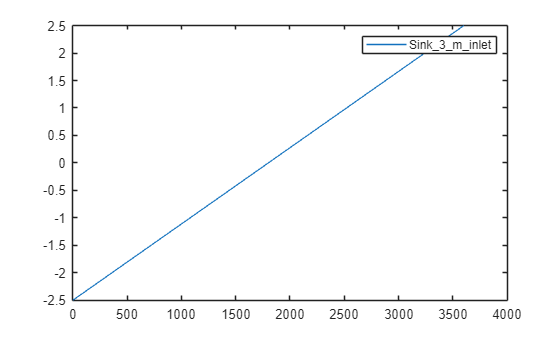

% Define the time vector and initial conditions for simulation
t = 1:1:3600;
x0 = ones(1, mdl.n) * 273.15 + 30; % Initial temperature
u = [
    linspace(-2.5, 2.5,length(t))',... % Varying input
    ones(length(t),1)*273.15+30,... % Constant temperature input
    ones(length(t), 1) * 2e5 % Zero input for the third variable
];
result = dmsim(mdl, x0, [],[],t, u);

plot(result.tsim, result.y(:,idx(1)),'DisplayName',output_strings(1))
legend('Interpreter','none')

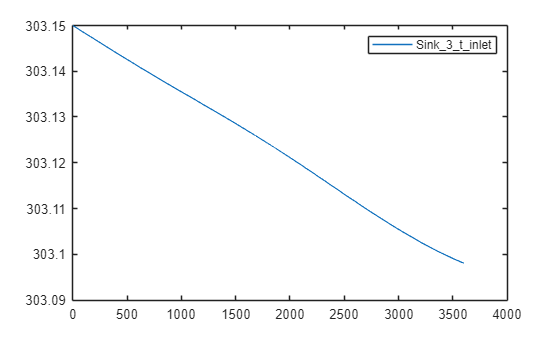

plot(result.tsim, result.y(:,idx(2)),'DisplayName',output_strings(2))
legend('Interpreter','none')

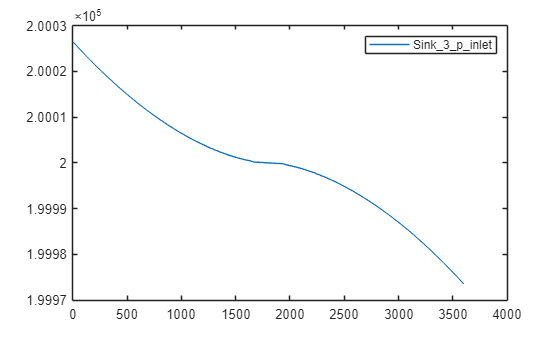

plot(result.tsim, result.y(:,idx(3)),'DisplayName',output_strings(3))
legend('Interpreter','none')